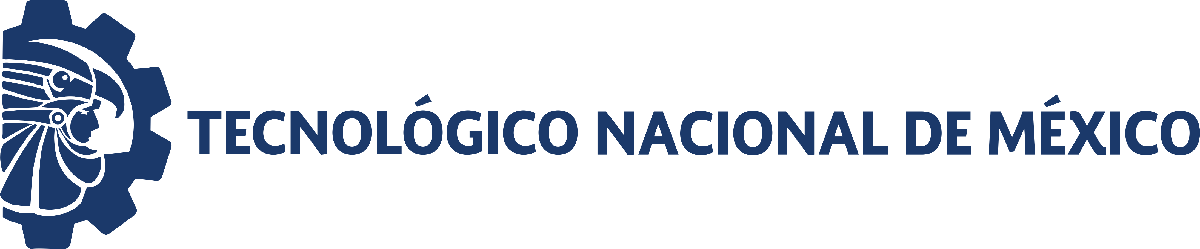                                 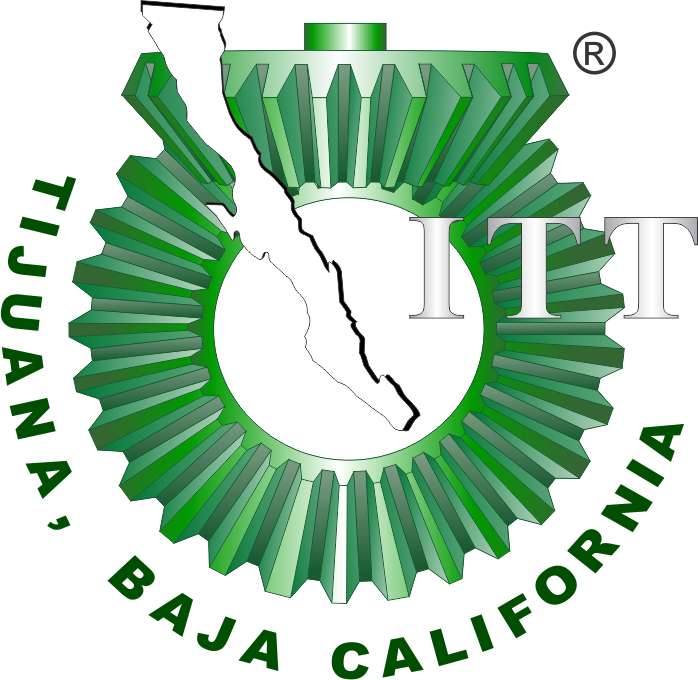

# Práctica 4: Sistema endocrino 

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

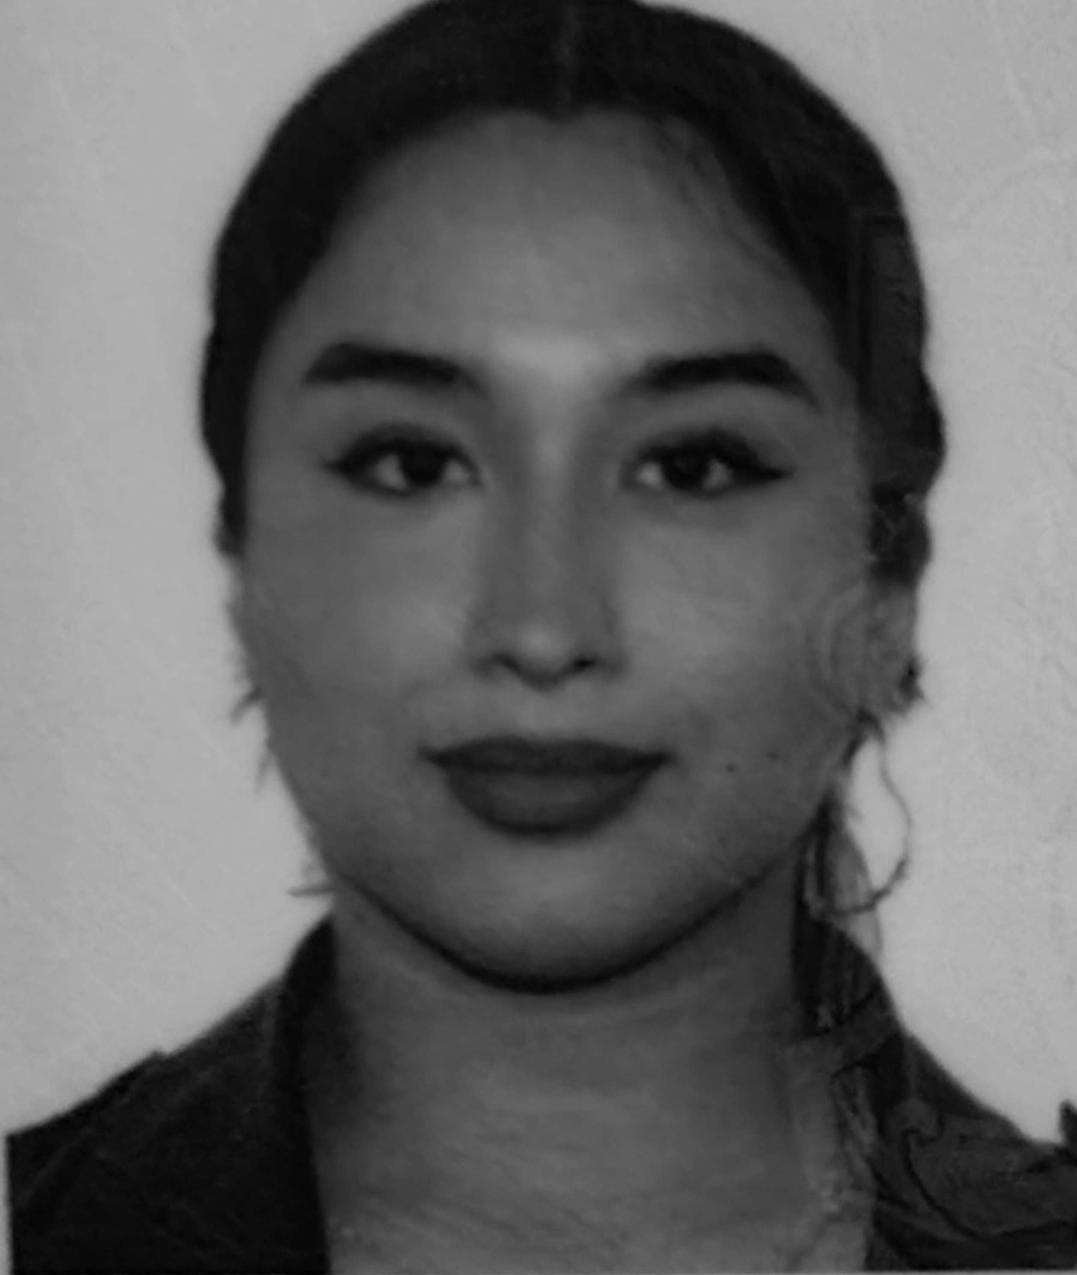

Nombre del alumno: **Osiris Jaylin Chavez Hernandez**

Número de control: **23210721**

Correo institucional: **l23210721@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')

tend = '10';
file = 'Sistema';

open_system(file);

parameters.StopTime = tend;
parameters.Solver = 'ode15s';
parameters.MaxStep = '1E-3';

x = sim(file, parameters);

## Respuesta del sistema

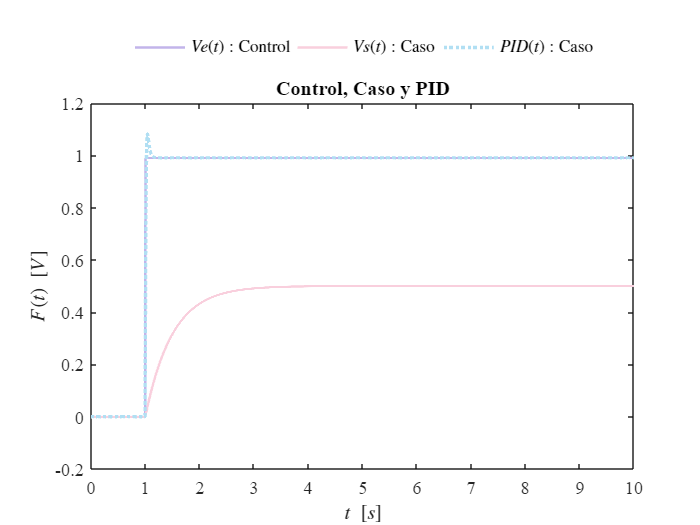

plotsignals(x.t, x.Pp1, x.Pp3, x.PID1)

## Función respuesta del sistema

function plotsignals(t, control, caso, PID1)

set(figure(), 'Color', 'w')
box on; hold on;

colors = [194, 180, 234;
          249, 207, 221;
          177, 223, 243]/255;
colororder(colors)

P = plot(t, control, '-', ...
         t, caso, '-', ...
         t, PID1, ':', ...
         'LineWidth', 1.5);

set(P(3), 'LineWidth', 2)

L = legend('$Ve(t): \mathrm{Control}$', ...
           '$Vs(t): \mathrm{Caso}$', ...
           '$PID(t): \mathrm{Caso}$');

set(L, 'Interpreter',  'Latex', ...
       'FontSize',      10, ...
       'Location',      'NorthOutside', ...
       'Box',           'Off', ...
       'Orientation',   'Horizontal');

xlabel('$t\ [s]$',    'Interpreter', 'Latex', 'FontSize', 11)
ylabel('$F(t)\ [V]$', 'Interpreter', 'Latex', 'FontSize', 11)

xlim([0, 10]); 
xticks(0:1:10);

ylim([-0.2, 1.2]); 
yticks(-0.2:0.2:1.2);

title('Control, Caso y PID')

set(gca, 'FontName', 'Times New Roman', 'FontSize', 11)

exportgraphics(gcf, 'endocrino_control_caso_PID.pdf', 'ContentType', 'vector')

end